# **Exercise n°1-2**

clc
clear

- ** Part 1:**

Parameters:

x_i = 0; y_i = 0; theta_i = 0;
l = 1;

%%% Computation of final coordinates
a = rand(1,3); % generation of vector 1x3 of random values
q_f = a./norm(a,2) % because ||q_f - q_i||=1 is satisfied always in this way

q_f =     0.8190    0.5670    0.0875


x_f = q_f(1,1); y_f = q_f(1,2); theta_f = q_f(1,3);

%%% Parameters of Cartesian cubic polinomial
k = 20 % by choosing k_i=k_f to reduce the number of degrees of freedom

k = 20

if k == 0
    disp('Value of k not valid!')
end

ds = 0.001;
s = 0:ds:l;

alpha_x = k*cos(theta_f) - 3*x_f;
alpha_y = k*sin(theta_f) - 3*y_f;
beta_x = k*cos(theta_i) + 3*x_i;
beta_y = k*sin(theta_i) + 3*y_i;

%%% Parameters for time law
v_max = 0.5; % m/s
w_max = 2; %rad/s

Cubic Cartesian polynomial:

x_s = s.^3.*x_f-(s-1).^3.*x_i+alpha_x.*s.^2.*(s-1)+beta_x.*s.*(s-1).^2;
y_s = s.^3.*y_f-(s-1).^3.*y_i+alpha_y.*s.^2.*(s-1)+beta_y.*s.*(s-1).^2;

Plot of the trajectory path:

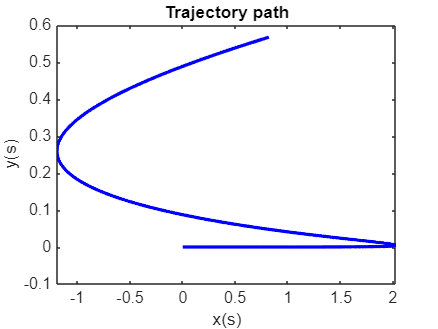

plot(x_s,y_s,'b','LineWidth',2)
title('Trajectory path')
xlabel('x(s)')
ylabel('y(s)')

With the flat outputs it's possible to reconstruct the inputs and to compute the angular motion.

It must need the prime derivatives and second derivatives of the cubic Cartesian polinomial:

x_s_prime = 3.*s.^2*x_f-3.*(s-1).^2*x_i+alpha_x.*(3.*s.^2-2.*s)+beta_x.*(s-1).^2+beta_x.*s*2.*(s-1);
y_s_prime = 3.*s.^2*y_f-3.*(s-1).^2*y_i+alpha_y.*(3.*s.^2-2.*s)+beta_y.*(s-1).^2+beta_y.*s*2.*(s-1);
x_s_sec = 6.*s*x_f-6*(s-1)*x_i+alpha_x.*(6.*s-2)+beta_x*2.*(s-1)+beta_x*2.*(2.*s-1);
y_s_sec = 6.*s*y_f-6*(s-1)*y_i+alpha_y.*(6.*s-2)+beta_y*2.*(s-1)+beta_y*2.*(2.*s-1);

%supposing forward motion
theta_s = atan2(x_s_prime,y_s_prime);
v_tilde_s = sqrt(x_s_prime.^2 + y_s_prime.^2);
w_tilde_s = (y_s_sec.*x_s_prime - x_s_sec.*y_s_prime)./(x_s_prime.^2 + y_s_prime.^2);


Computation of control inputs (heading velocity and angular velociity) respect to flat output:

t_i = 0

t_i = 0

t_f = 10

t_f = 10

T = t_f - t_i

T = 10

dt=T/(size(s,2)-1); % because t must need the same dimension of elements of s
dtau= dt/T;

t=t_i:dt:t_f;
s_dot = ds/dt;
v_t = v_tilde_s*s_dot

v_t =     2.0000    1.9885    1.9771    1.9656    1.9542    1.9428    1.9315    1.9201    1.9088    1.8975    1.8862    1.8750    1.8637    1.8525    1.8413    1.8302    1.8190    1.8079    1.7968    1.7858    1.7747    1.7637    1.7527    1.7417    1.7308    1.7198    1.7089    1.6981    1.6872    1.6764    1.6655    1.6547    1.6440    1.6332    1.6225    1.6118    1.6011    1.5905    1.5798    1.5692    1.5586    1.5481    1.5375    1.5270    1.5165    1.5061    1.4956    1.4852    1.4748    1.4644


w_t = w_tilde_s*s_dot

w_t =    -0.0005   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006


Verification of the control inputs limits:

for i = 1:size(v_t,2)
    if v_t(1,i) > v_max
        T = (v_tilde_s(1,i)*ds/dtau)/v_max % new increased T
        
        t_f = t_i + T% new final time
        dt=T/(size(s,2)-1); % new dt
        dtau = dt/T % new tau

        t=t_i:dt:t_f; % new time interval
        s_dot = ds/dt; % new s_dot
        v_t = v_tilde_s*ds/dtau*1/T % new heading velocity in time
        w_t = w_tilde_s*ds/dtau*1/T % new angular velocity in time
    end
end

T = 40

t_f = 40

dtau = 1.0000e-03

v_t =     0.5000    0.4971    0.4943    0.4914    0.4886    0.4857    0.4829    0.4800    0.4772    0.4744    0.4716    0.4687    0.4659    0.4631    0.4603    0.4575    0.4548    0.4520    0.4492    0.4464    0.4437    0.4409    0.4382    0.4354    0.4327    0.4300    0.4272    0.4245    0.4218    0.4191    0.4164    0.4137    0.4110    0.4083    0.4056    0.4030    0.4003    0.3976    0.3950    0.3923    0.3897    0.3870    0.3844    0.3818    0.3791    0.3765    0.3739    0.3713    0.3687    0.3661


w_t =    -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


for j = 1:size(w_t,2)
    if w_t(1,i) > w_max
        T = (v_tilde_s(1,i)*ds/dtau)/v_max % new increased tau
        t_f = T - t_i % new final time
        dt=T/(size(s,2)-1);
        dtau = dt/T % new tau

        t=t_i:dt:t_f; % new time interval
        s_dot = ds/dt; % new s_dot
        v_t = v_tilde_s*ds/dtau*1/T % new heading velocity in time
        w_t = w_tilde_s*ds/dtau*1/T % new angular velocity in time
    end
end

Desired heading velocity and angular velocity plots:

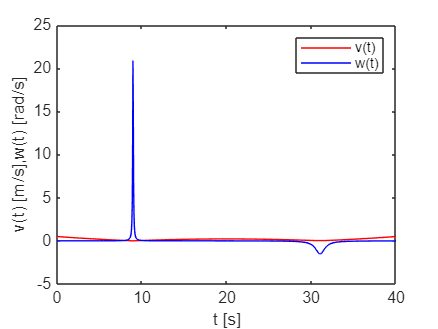

plot(t, v_t,'r', t, w_t, 'b','LineWidth',0.5)
xlabel('t [s]')
ylabel('v(t) [m/s],w(t) [rad/s]')
legend('v(t)','w(t)')

- Part 2:

Parameters:

b = 0.01; % distance of the new point B from the center of the unicycle in the sagittal plane

k_1 = 50; k_2 = 50; % controller gains

if b == 0
    disp('Choose a value of distance b different from 0.')
elseif k_1 <= 0 || k_2 <= 0
    disp('Not valid gains.')
else
    % coordinates of B
    y_1 = zeros(size(s));
    y_2 = zeros(size(s));
    y_1(1,1) = x_i + b*cos(theta_i);
    y_2(1,1) = y_i + b*sin(theta_i);

    %real theta
    theta_r = zeros(size(s));
    theta_r(1,1) = theta_i;

    %real heading velocity and angular velocities
    v_r = zeros(size(s));
    w_r = zeros(size(s)); 
    
    %errors
    e_1 = zeros(size(s));
    e_2 = zeros(size(s));

    %Previous desired coordinates initialization
    y_1d_p = 0;
    y_2d_p = 0;

    for i=2:size(s,2)
        y_1d = x_s(1,i)+b*cos(theta_s(1,i));
        y_2d = y_s(1,i)+b*sin(theta_s(1,i));

        % Derivatives of the desired y_1 and y_2
        y_1d_dot = (y_1d - y_1d_p)/dt;
        y_2d_dot = (y_2d - y_2d_p)/dt;

        % Computation of the error
        e_1(1,i) = y_1d - y_1(1,i-1); 
        e_2(1,i) = y_2d - y_2(1,i-1);
        
        % Computations of the control inputs with a simple controller
        u_1 = y_1d_dot + k_1*e_1(1,i);
        u_2 = y_2d_dot + k_2*e_2(1,i);

        % Computation of the output
        T_theta = [cos(theta_r(1,i-1)) -b*cos(theta_r(1,i-1));
            sin(theta_r(1,i-1)) b*cos(theta_r(1,i-1))];
        q = inv(T_theta)*[u_1 u_2]'; %system output vector
        v_r(1,i) = q(1,1);
        w_r(1,i) = q(2,1);

        theta_r(1,i) = theta_r(1,i-1) + w_r(1,i)*ds;
        y_1(1,i) = y_1(1,i-1) + v_r(1,i)*cos(theta_r(1,i))*ds;
        y_2(1,i) = y_2(1,i-1) + v_r(1,i)*sin(theta_r(1,i))*ds;

        %Previous desired coordinates
        y_1d_p = y_1d;
        y_2d_p = y_2d;
    end
end

Differents between the desired trajectory path and the computed one by the controller:

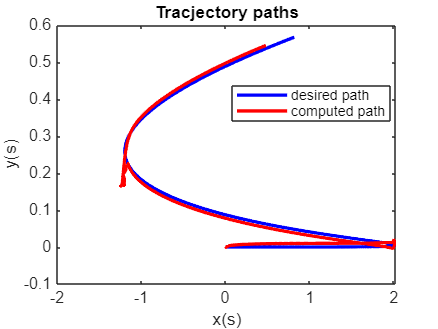

x_r = y_1 - b.*cos(theta_r);
y_r = y_2 - b.*sin(theta_r);
plot(x_s,y_s,'b',x_r,y_r,'r','LineWidth',2)
title('Tracjectory paths')
legend('desired path','computed path','Location','best')
xlabel('x(s)')
ylabel('y(s)')

Error behaviour:

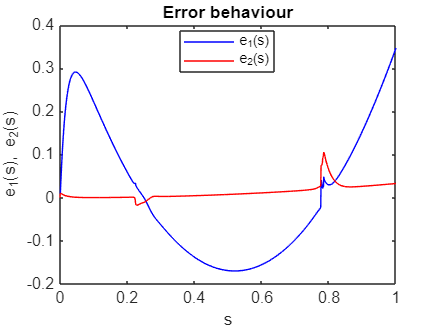

plot(s,e_1,'b',s,e_2,'r')
title('Error behaviour')
legend('e_1(s)','e_2(s)','Location','best')
xlabel('s')
ylabel('e_1(s), e_2(s)')

Obtained heading and angular velocities:

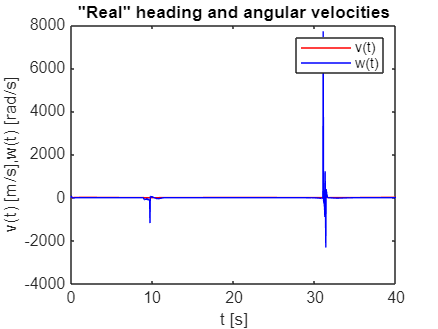

plot(t, v_r,'r', t, w_r, 'b','LineWidth',0.5)
title('"Real" heading and angular velocities')
xlabel('t [s]')
ylabel('v(t) [m/s],w(t) [rad/s]')
legend('v(t)','w(t)')